# Hormigón EHE-08

## Ejemplo 2

Este ejemplo consiste en la creación de una sección de hormigón pretensado y el análisis de las propiedades calculadas específicas de las secciones pretensadas. Posteriormente, se calcula y grafica el momento de fisuración (en función de la directa aplicada) y la inercia equivalente (en función de la directa y el momento flector aplicados). Se recomienda leer y replicar previamente el [ejemplo 1](https://htmlpreview.github.io/?https://github.com/quelopelo/hormigon-ehe08/blob/main/docs/ejemplo1.html).

### Ingresar la sección de hormigón

En este ejemplo se trabaja con una sección circular de hormigón pretensado (sin armadura pasiva), con la armadura activa distribuida en el perímetro.

En primer lugar, se definen los parámetros de los materiales y de la geometría de la sección a generar.

clear
run('..\init')

fck = 35;                   % Resistencia característica a compresión del hormigón (MPa)
fpk = 1600;                 % Límite elástico característico del acero (MPa)
fp = 0.8 * 1200;            % Tensión inicial (con pérdidas) de pretensado en cada barra (MPa)
r = 75;                     % Radio de la sección (mm)
rm = 25;                    % Recubrimiento mecánico perimetral (mm)
np = 8;                     % Cantidad de barras de acero
Api = pi * (5/2)^2;         % Área de acero de cada barra, correspondiente a Φ5 mm (mm2)

En segundo lugar, se generan las matrices 'geoHorm' y 'geoAcero' que contienen las propiedades geométricas del hormigón y del acero activo. Luego, se crea la sección mediante la función **crear_seccion**. La ayuda de esta función contiene información adicional de cómo se deben generar las matrices 'geoHorm' y 'geoAcero', así como de otros parámetros que pueden añadirse.

% Matriz de geometría del hormigón
angleVec = linspace(-pi/2, pi/2, 50)';
bVec = 2 * r * cos(angleVec);
yVec = r * sin(angleVec);
geoHorm = [yVec bVec];

% Matriz de geometría del acero pasivo
angleVec = linspace(0, 2*pi * (1 - 1/np), np)';
geoAcero = [(r - rm) * sin(angleVec), repmat(Api, [np, 1]), repmat(fp, [np, 1])];

% Sección de hormigón pretensado
S = crear_seccion(geoHorm, fck, [], [], [], [], geoAcero, fpk);

El estructurado 'S' contiene la información ingresada y otras propiedades calculadas, que dependen únicamente de la sección (y no de las solicitaciones actuantes). En lo que queda de este ejemplo se trabaja con la sección generada.

### Obtener propiedades de la sección

Además de la información explicada en el [ejemplo 1](https://htmlpreview.github.io/?https://github.com/quelopelo/hormigon-ehe08/blob/main/docs/ejemplo1.html), los campos 'S.eInf0' y 'S.eSup0' refieren a la pareja de deformaciones correspondiente a la ley plana de deformaciones que provoca la carga inicial de pretensado.

fprintf("Las deformaciones unitarias de los extremos inferior y superior debidas al pretensado son: %.5f y %.5f\n", S.eInf0, S.eSup0)

Las deformaciones unitarias de los extremos inferior y superior debidas al pretensado son: -0.00038 y -0.00038


### Calcular el momento de fisuración

En esta sección se grafica el momento de fisuración (no lineal) en función de la directa aplicada.

En primer lugar, se generan los vectores de directa y de momento de fisuración mediante la función **momento_fisuracion**. La ayuda de esta función contiene información adicional de cómo se debe llamar a esta función, así como de los valores que retorna.

NVec = linspace(S.NMin, S.NMax, 100);           % Vector de directas (N)
MfVec = zeros(size(NVec));                      % Vector de momentos de fisuración correspondientes (N.mm)
for i = 1 : length(NVec)
    [~, Mfi] = momento_fisuracion(NVec(i), S);
    MfVec(i) = Mfi;
end
NVec = NVec/1e3;                                % Vector de directas (kN)
MfVec = MfVec/1e6;                              % Vector de momentos de fisuración correspondientes (kN.m)

Los primeros valores del vector 'MfVec' valen 'inf' porque, para esas directas (de compresión), la sección falla antes de llegar a la fisuración.

En segundo lugar, se realiza el gráfico. Obsérvese que el código es relativamente extenso para mejorar la presentación del diagrama de interacción, pero podría reducirse solamente a la última línea.

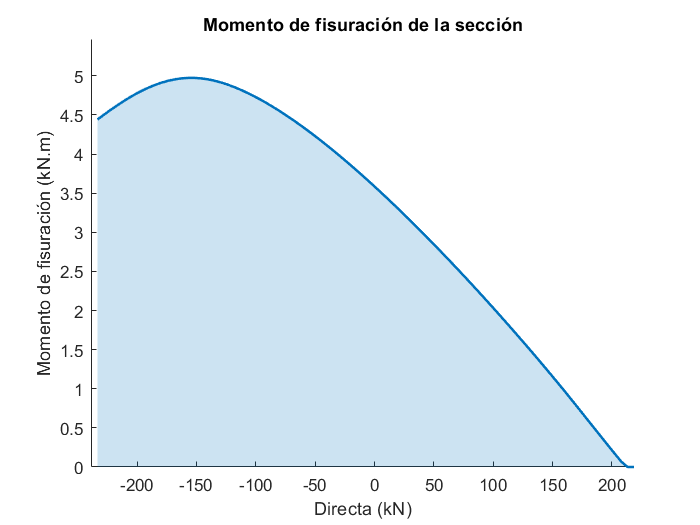

figure
title("Momento de fisuración de la sección")
xlabel("Directa (kN)")
ylabel("Momento de fisuración (kN.m)")
xlim([max(NVec(MfVec == inf)), max(NVec)])
ylim([0, 1.1*max(MfVec(MfVec ~= inf))])

hold on
area(NVec, MfVec, "LineStyle", "none", "FaceAlpha", 0.2)
plot(NVec, MfVec, "Color", "#0072BD", "LineWidth", 1.5)

### Calcular la rigidez fisurada y equivalente

En esta sección se grafica la rigidez equivalente (no lineal) en función del momento flector aplicado para distintas directas. El cálculo de la rigidez fisurada se hace de manera análoga, llamando a la función correspondiente.

En primer lugar, se generan los vectores de directa y de momento flector, y la matriz de inercias equivalentes mediante la función **rigidez_flexional_equivalente**. Si en lugar de la rigidez equivalente se desea obtener la rigidez fisurada, entonces basta con sustituir la función anterior por la función **rigidez_flexional_fisurada**, cuyos parámetros de entrada y formato de salida son idénticos (ver ayudas de las dos funciones). Dentro del ciclo anidado se utiliza la función **coeficiente_solicitaciones_normales**, cuyo funcionamiento se explica con más detalle en el [ejemplo 3](https://htmlpreview.github.io/?https://github.com/quelopelo/hormigon-ehe08/blob/main/docs/ejemplo3.html). En este caso, se emplea para calcular la inercia fisurada únicamente en los casos en que la sección verifica la pareja de solicitaciones (directa y momento flector).

NVec = linspace(-2e5, 2e5, 5)';                 % Vector de directas (N)
MVec = linspace(0, S.MMax, 100);                % Vector de momentos flectores (N.mm)
EIeVec = zeros(length(NVec), length(MVec));     % Matriz de inercia equivalente (N.mm2) para cada directa y momento flector
for i = 1 : length(NVec)
    for j = 1 : size(EIeVec, 2)
        coefi = coeficiente_solicitaciones_normales(NVec(i), MVec(j), S);
        if coefi <= 1
            EIeVec(i, j) = rigidez_flexional_equivalente(NVec(i), MVec(j), S);
        else
            EIeVec(i, j) = NaN;
        end
    end
end
NVec = NVec/1e3;                                % Vector de directas (kN)
MVec = MVec/1e6;                                % Vector de momentos flectores (kN.m)
EIeVec = EIeVec/1e9;                            % Matriz de inercia equivalente (kN.m2) para cada directa y momento flector

En segundo lugar, se realiza el gráfico. Al igual que en la sección anterior, obsérvese que el código es relativamente extenso para mejorar la presentación del diagrama de interacción, pero podría reducirse solamente a las últimas cuatro líneas.

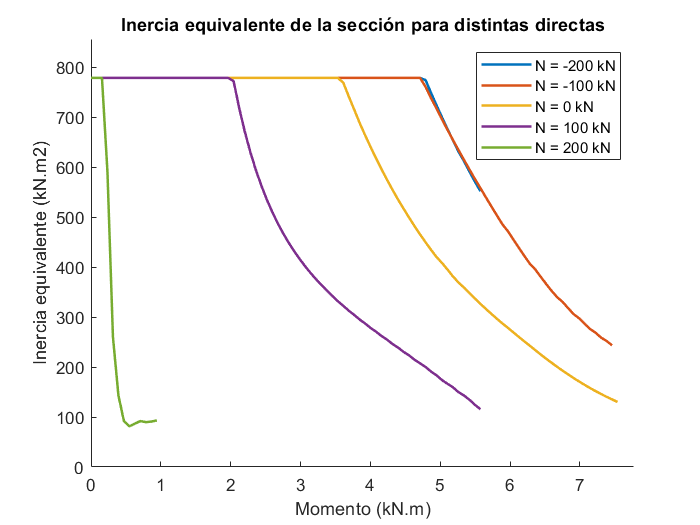

figure
title("Inercia equivalente de la sección para distintas directas")
xlabel("Momento (kN.m)")
ylabel("Inercia equivalente (kN.m2)")
xlim([0, S.MMax]/1e6)
ylim([0, 1.1*max(max(EIeVec))])

hold on
for i = 1 : length(NVec)
    plot(MVec, EIeVec(i, :), "LineWidth", 1.5, "DisplayName", "N = " + num2str(NVec(i)) + " kN")
end
legend